# Ejercicio 3.01  

Usa la Robotics System Toolbox v2.2

Transformación homogénea en una cuña cúbica.

% Dibujamos el cubo que contiene la cuña
a=1; b=1; c=1;
voxel([0 0 0],[a b c],'r',0.1);
grid on		% Se establece una rejilla
view(-60,30)	% Se establece el punto de vista
axis equal

% Representación del frame 0:
T0=eye(4);
pframe(T0,'c',.4);


Las sucesivas transformaciones se refieren a los ejes globales, y por ello las matrices se pre-multiplican.

% el frame 1, en color verde:
T1=trvec2tform([0 0 c]) * axang2tform([0 0 1 -pi/2]) * axang2tform([0 1 0 pi/2])*T0

T1 =     0.0000    1.0000    0.0000         0
   -0.0000    0.0000   -1.0000         0
   -1.0000         0    0.0000    1.0000
         0         0         0    1.0000


pframe(T1,'g',.4);

% el frame 2, en azul:
T2=trvec2tform([0 b 0]) * axang2tform([0 0 1 -pi/2]) * axang2tform([1 0 0 pi/2])*T0

T2 =     0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000    1.0000
         0    1.0000    0.0000         0
         0         0         0    1.0000


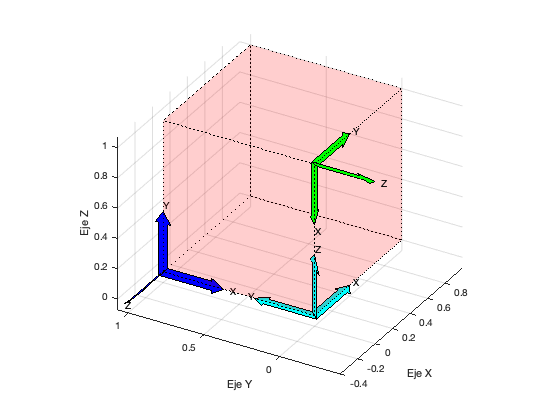

pframe(T2,'b',.4);


% el punto para el frame 2:
p2=inv(T2)*[1 1 1 1]'

p2 =     0.0000
    1.0000
   -1.0000
    1.0000


# Otra versión

Version sin pframe, con un sólido definido en P=psolido.m y en coordenadas homogéneas.

Usa la Robotics System Toolbox v2.2

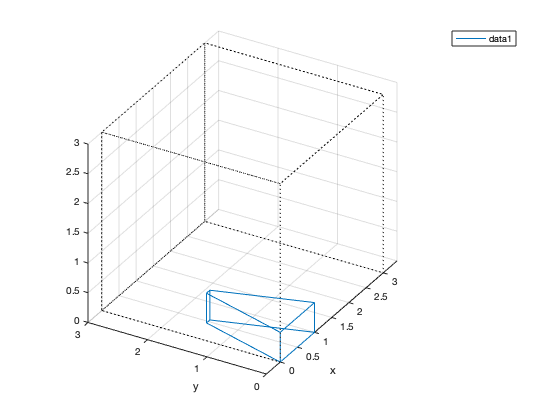

clf
a=3; b=3; c=3;
voxel([0 0 0],[a b c],'r',0);
axis equal; grid
view(-60,30); hold on
P=psolido; % devuelve un objeto prismático en P ó Ph
% Para dibujarlo con plot3 es más cómoda la traspuesta:
Pp=P'; h1=plot3(Pp(:,1),Pp(:,2)',Pp(:,3)');
xlabel('x'); ylabel('y'); legend([h1])

Hacemos tres giros respecto a X,Y,Z respectivamente.

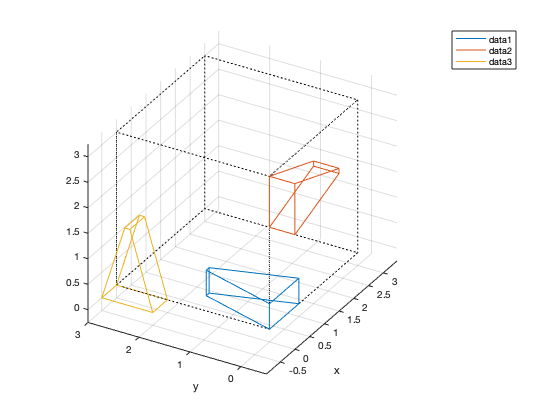

% Los pasamos a coodenadas homogéneas:
Ph = cart2hom(P'); Ph=Ph';
% Giro 1:
T1=trvec2tform([0 0 c]) * axang2tform([0 0 1 -pi/2]) * axang2tform([0 1 0 pi/2]);
Ph  = T1 * Ph;
Pp=Ph'; h2=plot3(Pp(:,1),Pp(:,2),Pp(:,3)); 
legend([h1 h2])
% Giro 2:
T1=trvec2tform([0 b 0]) * axang2tform([0 0 1 -pi/2]) * axang2tform([1 0 0 pi/2]);

P=psolido;
% Los pasamos a coodenadas homogéneas:
Ph = cart2hom(P'); Ph=Ph';

Ph  = T1 * Ph;
Pp=Ph'; h3=plot3(Pp(:,1),Pp(:,2),Pp(:,3));
legend([h1 h2 h3])